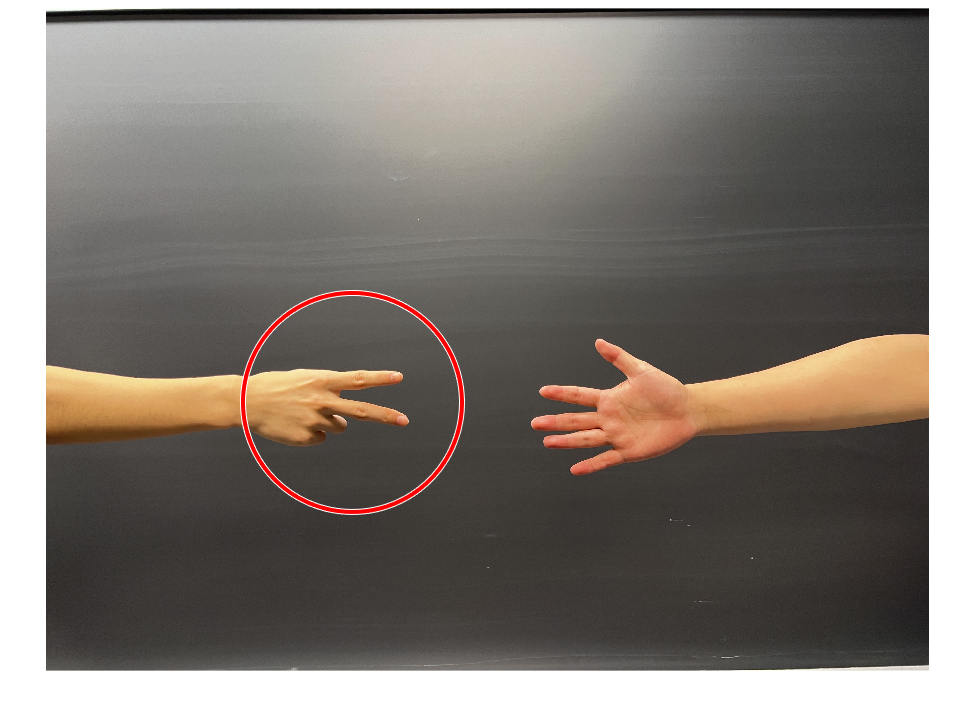

% step 1
img1 = imread("G1.jpg");
img2 = imread("G2.jpg");
img3 = imread("G3.jpg");
img4 = imread("G4.jpg");
img5 = imread("G5.jpg");
rock = imread("rock.jpg");
paper = imread("paper.jpg");
scissor = imread('scissor.jpg');

bg1 = imread("BG1.JPG");
bg2 = imread("BG2.JPG");
bgm = (bg1+bg2)/2;

output1 = regionExtraction(img1, bgm, 100);
output2 = regionExtraction(img2, bgm, 100);
output3 = regionExtraction(img3, bgm, 100);
output4 = regionExtraction(img4, bgm, 100);
output5 = regionExtraction(img5, bgm, 50);

[rockr, rockc, rd] = size(rock);
[paperr, paperc, pd] = size(paper);
[scissorr, scissorc, sd] = size(scissor);
bgrock = bgm(1500:1500+rockr, 1:rockc, :);
bgpaper = bgm(1500:1500+paperr, 1:paperc, :);
bgscissor = bgm(1500:1500+scissorr, 1:scissorc, :);
rockT = regionExtraction(rock, bgrock, 100);
paperT = regionExtraction(paper, bgpaper, 100);
scissorT = regionExtraction(scissor, bgscissor, 100);

%step 2
rock_G = imresize(double(rockT), 0.1);
paper_G = imresize(double(paperT), 0.1);
scissor_G = imresize(double(scissorT), 0.1);
output1 = imresize(double(output1), 0.1);
output2 = imresize(double(output2), 0.1);
output3 = imresize(double(output3), 0.1);
output4 = imresize(double(output4), 0.1);
output5 = imresize(double(output5), 0.1);

subImg1L = extractImg(output1, rock_G);
subImg2L = extractImg(output2, rock_G);
subImg3L = extractImg(output3, rock_G);
subImg4L = extractImg(output4, rock_G);
subImg5L = extractImg(output5, rock_G);
%rotate images
output1 = imrotate(output1', -90);
output2 = imrotate(output2', -90);
output3 = imrotate(output3', -90);
output4 = imrotate(output4', -90);
output5 = imrotate(output5', -90);

subImg1R = extractImg(output1, rock_G);
subImg2R = extractImg(output2, rock_G);
subImg3R = extractImg(output3, rock_G);
subImg4R = extractImg(output4, rock_G);
subImg5R = extractImg(output5, rock_G);

%step 3
rock1L= NCC(rock_G, subImg1L);
paper1L = NCC(paper_G, subImg1L);
scissor1L = NCC(scissor_G, subImg1L);
%imshow(subImg1L);
value1L = [rock1L, paper1L, scissor1L];

rock2L= NCC(rock_G, subImg2L);
paper2L = NCC(paper_G, subImg2L);
scissor2L = NCC(scissor_G, subImg2L);
%imshow(subImg2L);
value2L = [rock2L, paper2L, scissor2L];

rock3L= NCC(rock_G, subImg3L);
paper3L = NCC(paper_G, subImg3L);
scissor3L = NCC(scissor_G, subImg3L);
%imshow(subImg3L);
value3L = [rock3L, paper3L, scissor3L];

rock4L= NCC(rock_G, subImg4L);
paper4L = NCC(paper_G, subImg4L);
scissor4L = NCC(scissor_G, subImg4L);
%imshow(subImg4L);
value4L = [rock4L, paper4L, scissor4L];

rock5L= NCC(rock_G, subImg5L);
paper5L = NCC(paper_G, subImg5L);
scissor5L = NCC(scissor_G, subImg5L);
%imshow(subImg5L);
value5L = [rock5L, paper5L, scissor5L];

rock1R= NCC(rock_G, subImg1R);
paper1R = NCC(paper_G, subImg1R);
scissor1R = NCC(scissor_G, subImg1R);
%imshow(subImg1R);
value1R = [rock1R, paper1R, scissor1R];

rock2R= NCC(rock_G, subImg2R);
paper2R = NCC(paper_G, subImg2R);
scissor2R = NCC(scissor_G, subImg2R);
%imshow(subImg2R);
value2R = [rock2R, paper2R, scissor2R];

rock3R= NCC(rock_G, subImg3R);
paper3R = NCC(paper_G, subImg3R);
scissor3R = NCC(scissor_G, subImg3R);
%imshow(subImg3R);
value3R = [rock3R, paper3R, scissor3R];

rock4R= NCC(rock_G, subImg4R);
paper4R = NCC(paper_G, subImg4R);
scissor4R = NCC(scissor_G, subImg4R);
%imshow(subImg4R);
value4R = [rock4R, paper4R, scissor4R];

rock5R= NCC(rock_G, subImg5R);
paper5R = NCC(paper_G, subImg5R);
scissor5R = NCC(scissor_G, subImg5R);
%imshow(subImg5R);
value5R = [rock5R, paper5R, scissor5R];

%1 for rock, 2 for paper, 3 for scissor
winNum = [0, 0];
win = 0;
[val, r1L] = max(value1L);
[val, r1R] = max(value1R);
round1 = [r1L, r1R];

[val, r2L] = max(value2L);
[val, r2R] = max(value2R);
round2 = [r2L, r2R];

[val, r3L] = max(value3L);
[val, r3R] = max(value3R);
round3 = [r3L, r3R];

[val, r4L] = max(value4L);
[val, r4R] = max(value4R);
round4 = [r4L, r4R];

[val, r5L] = max(value5L);
[val, r5R] = max(value5R);
round5 = [r5L, r5R];

%step 4
[l, r] = DetermineWin(round1, winNum, img1);

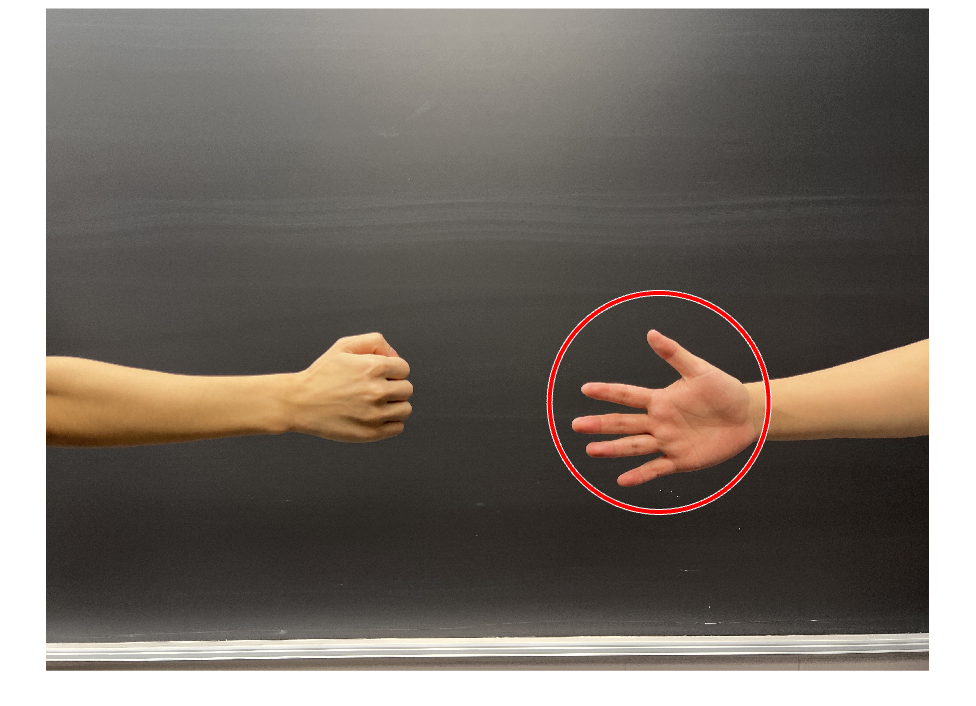

winNum = [l, r];
[l, r] = DetermineWin(round2, winNum, img2);

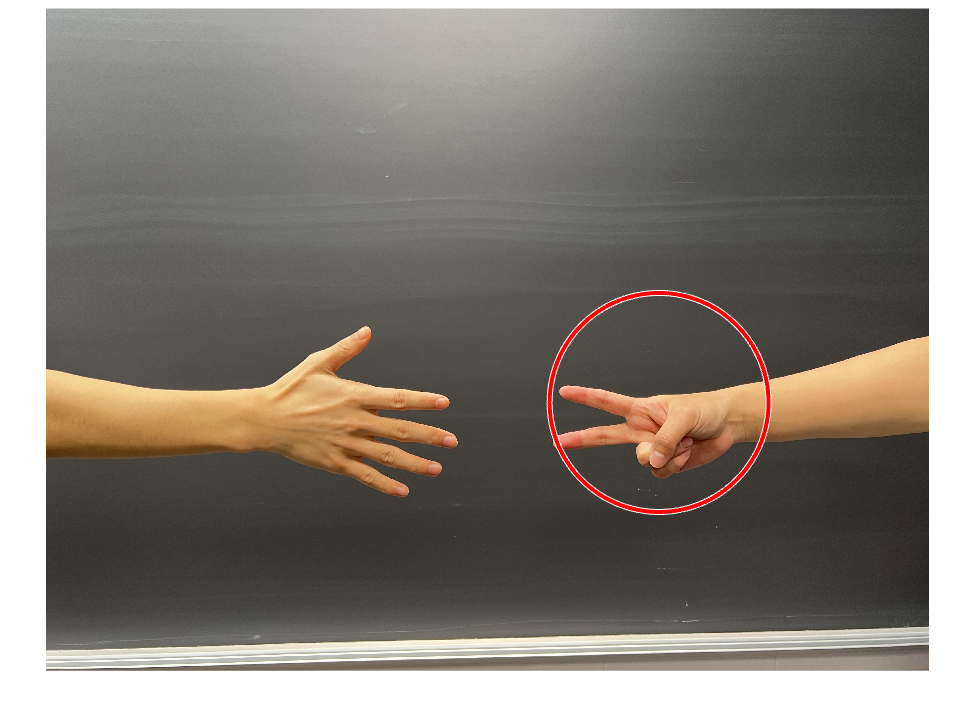

winNum = [l, r];
[l, r] = DetermineWin(round3, winNum, img3);

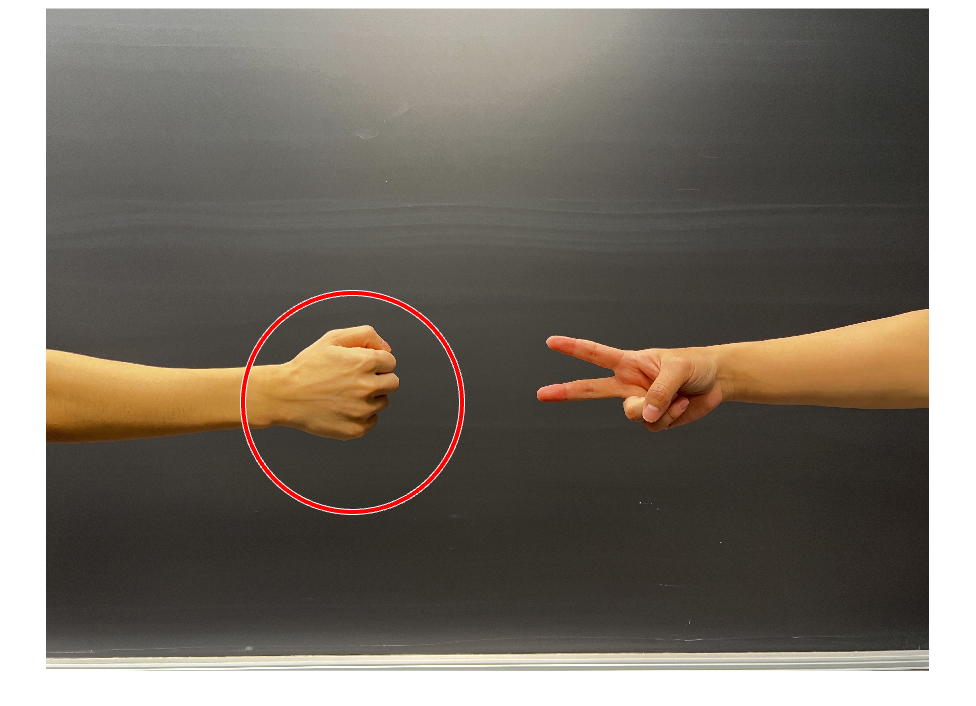

winNum = [l, r];
[l, r] = DetermineWin(round4, winNum, img4);

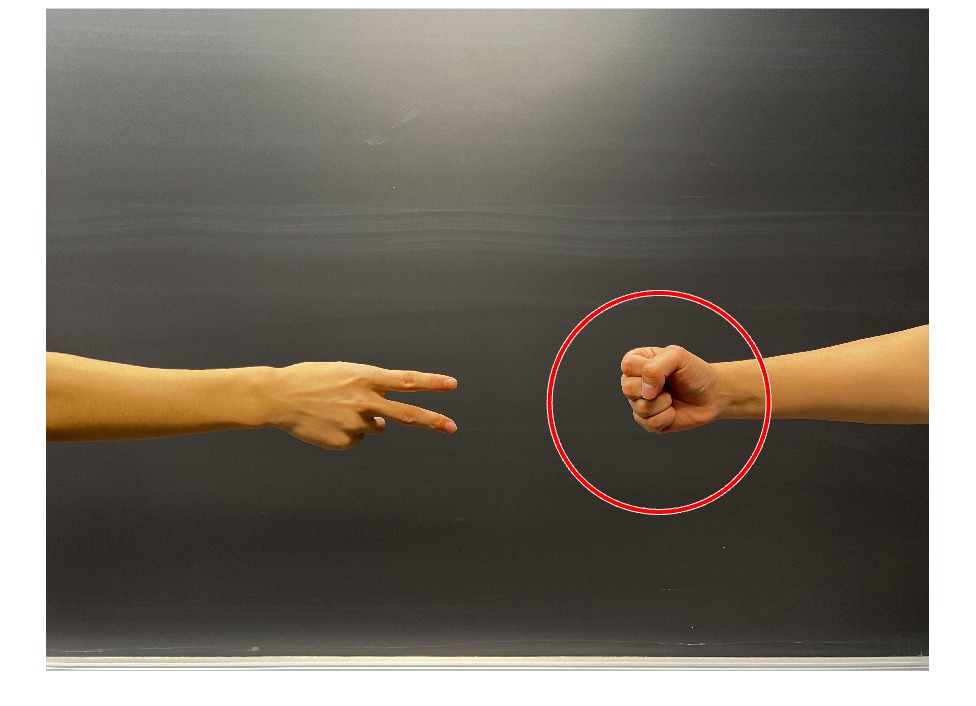

winNum = [l, r];
[l, r] = DetermineWin(round5, winNum, img5);

winNum = [l, r];
if l>=3
    win = 1;
    disp 'The left person is the winnner!'
elseif r >= 3
    win = 2;
    disp 'The right person is the winner!'
else 
    win = 3;
    disp 'No winner in 5 rounds.' 
end

The right person is the winner!


ratio = sprintf('Game score is %d : %d', l, r);
fprintf(ratio);

Game score is 2 : 3

function result = regionExtraction(img, bg, t)
    bgrm = double(bg(:, :, 1));
    bggm = double(bg(:, :, 2));
    bgbm = double(bg(:, :, 3));
    imgr = double(img(:, :, 1));
    imgg = double(img(:, :, 2));
    imgb = double(img(:, :, 3));
    [x, y] = size(imgr);
    result = ones(x, y);
    for i  = 1:x
        for j = 1:y
            temp = ((imgr(i, j)-bgrm(i, j))^2+(imgg(i, j)-bggm(i, j))^2+(imgb(i, j)-bgbm(i, j))^2)^(1/2);
            if temp < t
                result(i, j) = 0;
            end
        end
    end
end

%step 2
function subImg = extractImg(search, template)
    [row, col] = size(search);
    [rT, cT] = size(template);
    meanT = mean(template, [1,2]);
    stdevT = std(template, [], [1,2]);
    meanT= repmat(meanT, rT, cT);
    NormT = template - meanT;

    NccScore = zeros(row, col);
    NccFactor = rT*cT-1;
    for i = 1:row-rT+1
        for j = 1:col-cT+1
            temp = search(i:i+rT-1,j:j+cT-1);
            meanS = mean(temp, [1,2]);
            stdevS = std(temp, [], [1,2]);
            meanS = repmat(meanS, rT, cT);
            NormS = temp - meanS;
            comean=NormS.*NormT;
            coStd=repmat((stdevS.*stdevT), rT, cT);
            Ncc=sum(comean./coStd, 'all')/NccFactor;
            NccScore(i+floor(rT/2), j+floor(cT/2))=Ncc;
        end
    end
    NccSort=sort(NccScore(NccScore<5),'descend');
    [rowS, colS] = find(NccScore == NccSort(1));
    
    subImg = search(rowS-floor(rT/2)-20:rowS+floor(rT/2)+20, colS-floor(cT/2)-20:colS+floor(cT/2)+20);
end

%step 3
function a = NCC(template, hand)
    [row, col] = size(hand);
    [rT, cT] = size(template);
    meanT = mean(template, [1,2]);
    stdevT = std(template, [], [1,2]);
    meanT= repmat(meanT, rT, cT);
    NormT = template - meanT;

    NccScore = zeros(row, col);
    NccFactor = rT*cT-1;
    for i = 1:row-rT+1
        for j = 1:col-cT+1
            temp = hand(i:i+rT-1,j:j+cT-1);
            meanS = mean(temp, [1,2]);
            stdevS = std(temp, [], [1,2]);
            meanS = repmat(meanS, rT, cT);
            NormS = temp - meanS;
            comean=NormS.*NormT;
            coStd=repmat((stdevS.*stdevT), rT, cT);
            Ncc=sum(comean./coStd, 'all')/NccFactor;
            NccScore(i+floor(rT/2), j+floor(cT/2))=Ncc;
        end
    end
    a = max(NccScore, [], 'all');
end

%in step 4
function [l, r] = DetermineWin(gesture, num, img)
    leftG = gesture(1, 1);
    rightG = gesture(1, 2);
    win = 0;
    l = num(1, 1);
    r  = num(1,2);
    % 1 is rock, 2 is paper, 3 is scissor
    if leftG == 1
        if rightG == 2
            r = r+1;
            win = 2;
        elseif rightG == 3
            l = l+1;
            win = 1;
        end
    elseif leftG == 2
        if rightG == 1
            l = l+1;
            win = 1;
        elseif rightG == 3
            r = r+1;
            win = 2;
        end
    elseif leftG == 3
        if rightG== 1
            r = r+1;
            win = 2;
        elseif rightG == 2
            l = l+1;
            win = 1;
        end
    end
    if win == 1
        imshow(img);
        %hold on;
        center = [1400, 1800];
        radius = 500;
        viscircles(center, radius,'Color','r');
    end
    if win == 2
        imshow(img);
        %hold on;
        center = [2800, 1800];
        radius = 500;
        viscircles(center, radius,'Color','r');
    end
end